Load data


% load NPS value
main_dir = '/Volumes/spacetop_projects_cue';
NPSdf = readtable(fullfile(main_dir, 'analysis/fmri/nilearn/deriv01_signature/rampup_plateau/signature-NPS_sub-all_runtype-pvc_event-stimulus.tsv'),...
    'FileType', 'text', 'Delimiter', ',');

% load behavioral value
behdf = readtable(fullfile('/Users/h/Documents/projects_local/cue_expectancy','data/beh/sub-all_task-all_epoch-stim_events.tsv'), ...
    'FileType', 'text', 'Delimiter', '\t');
% calculate intersection
mergedf = innerjoin(NPSdf, behdf, 'Keys', 'singletrial_fname');

% trim based on value and remove if na

% plot the values
pain_idx = strcmpi(mergedf.runtype, 'pain');
pain_only = mergedf(pain_idx, :);
paindf = pain_only(~ismember(pain_only.sub, {'sub-0002'}), :);
%% contrast code
% Create a mapping from strings to numbers
mapper = containers.Map({'high_stim', 'med_stim', 'low_stim'}, [1, 0, -1]);

% Iterate over the stimulusintensity column and apply the mapping
for i = 1:height(paindf)
    if isKey(mapper, paindf.stimulusintensity{i})
        paindf.stim_con(i) = mapper(paindf.stimulusintensity{i});
    else
        paindf.stim_con(i) = NaN; % Handle unexpected or missing values
    end
end


mapper = containers.Map({'high_cue', 'low_cue'}, [1, -1]);

% Iterate over the stimulusintensity column and apply the mapping
for i = 1:height(paindf)
    if isKey(mapper, paindf.cue{i})
        paindf.cue_con(i) = mapper(paindf.cue{i});
    else
        paindf.cue_con(i) = NaN; % Handle unexpected or missing values
    end
end


%% remove NAN
paindf_clean_Y = remove_missing_behvalues(paindf, 'outcomerating');
paindf_clean_X = remove_missing_behvalues(paindf_clean_Y, 'cue_con');
paindf_clean = remove_missing_behvalues(paindf_clean_X, 'NPS');


% mean center
% Get unique subjects
uniqueSubs = unique(mergedf.sub);

% Loop through each subject to calculate and store the demeaned expectrating
for i = 1:length(uniqueSubs)
    subIndex = strcmp(paindf_clean.sub, uniqueSubs{i}); % Find indices of current subject
    subMean = mean(paindf_clean.expectrating(subIndex)); % Calculate mean expectrating for current subject
    paindf_clean.EXPECT_demean(subIndex) = paindf_clean.expectrating(subIndex) - subMean; % Subtract mean from each rating
    paindf_clean.EXPECT_CMC(subIndex) = subMean;
end


% paindf_clean.stimulusintensity(index)
% sublist is the list of unique values in mergedf.sub
sub_list = unique(paindf_clean.sub);
%% expect -> NPS -> outcome
for i= 1:length(sub_list)
    index = strcmpi(paindf_clean.sub, sub_list(i));
    model1_X{i} = paindf_clean.cue_con(index); %EXPECT_demean(index); % - mean(paindf_clean.expectrating(index)); %df.cue(index);  %
    model1_M{i} = paindf_clean.NPS(index); 
    model1_Y{i} = paindf_clean.outcomerating(index); 
    cov_mediation_paincue{i} = [ paindf_clean.stim_con(index) ];
end



% 10 remove 3 sd
% ________________________________________________________
wh_outlier = cellfun(@(x) abs(x - mean(x)) > 3*std(x), model1_M, 'UniformOutput', false);

for i= 1:1:length(sub_list)
% model1_Mremovedpts{i} = model1_M{i}(wh_outlier{i});
model1_Mtrimmed{i} = model1_M{i}(~wh_outlier{i});
model1_Xtrimmed{i} = model1_X{i}(~wh_outlier{i});
model1_Ytrimmed{i} = model1_Y{i}(~wh_outlier{i});
cov_mediation_paincue_trimmed{i} = cov_mediation_paincue{i}(~wh_outlier{i});
end

% 2) remove trials less than 10
ntrials_trimmed = cellfun(@length, model1_Mtrimmed);

create_figure('ntrials', 1, 2); 
hist(ntrials_trimmed, 30)
title('Number of trials')
xlabel('Number of trials'); ylabel('Num. Subjects')

wh_remove = ntrials_trimmed < 10;
disp('removing:')

removing:


sum(wh_remove)

ans = 0

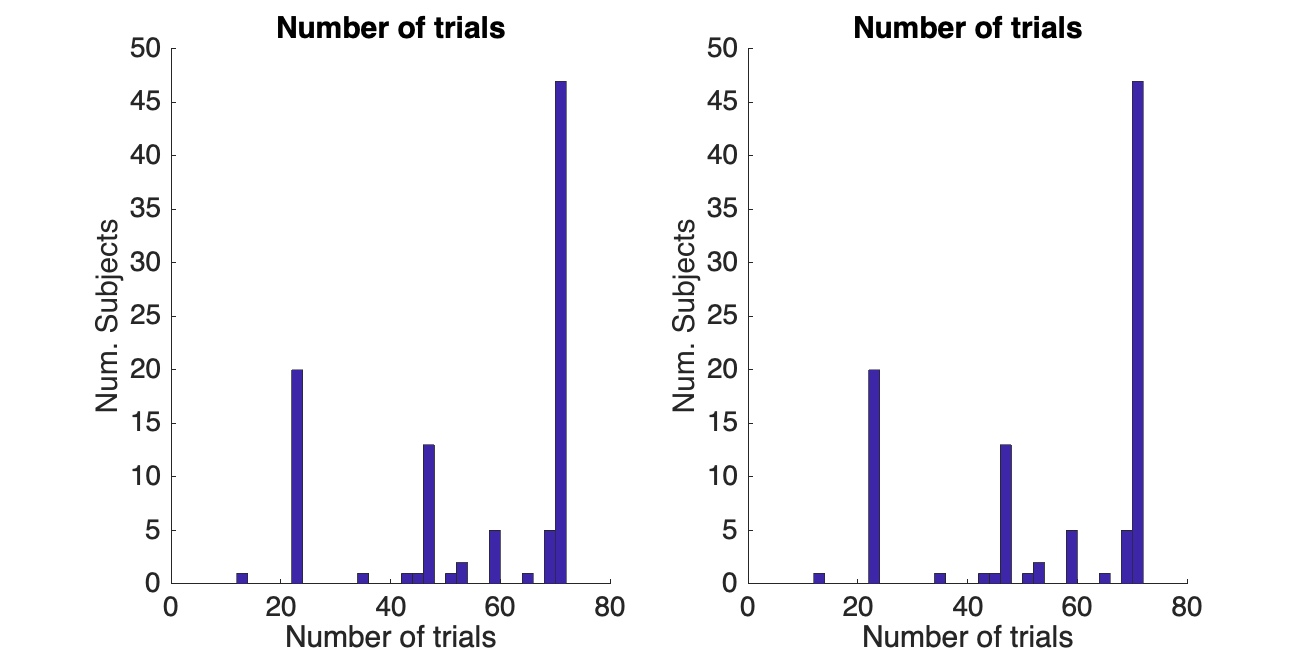


model1_X(wh_remove) = [];
model1_Xtrimmed(wh_remove) = [];
model1_Y(wh_remove) = [];
model1_Ytrimmed(wh_remove) = [];
model1_M(wh_remove) = [];
model1_Mtrimmed(wh_remove) = [];
cov_mediation_paincue(wh_remove) = [];
cov_mediation_paincue_trimmed(wh_remove) = [];

subplot(1, 2, 2); hist(ntrials_trimmed, 30)
title('Number of trials')
xlabel('Number of trials'); ylabel('Num. Subjects')


%% remove nan values from dataframes

meanx = cellfun(@nanmean, model1_Xtrimmed)';
meany = cellfun(@nanmean, model1_Ytrimmed)';
meanm = cellfun(@nanmean, model1_Mtrimmed)';
partialr = partialcorr([meanx meany meanm]);

t = array2table(partialr, 'VariableNames', {'Cue' 'Pain' 'NPS'});


# mediation

Mediation analysis

Observations:   1, Replications:  98
Predictor (X): Cue, Outcome (Y): Outcome rating: Mediator (M): NPS

Covariates: Yes,  98 columns

Multi-level analysis.
Options:
	Multilevel weights: Yes
	Plots: Yes
	Bootstrap: Yes
	Sign perm: No
	Robust: No
	Logistic(Y): No
	Bootstrap 1st level: No
	Bootstrap or sign perm samples: 10000

Getting estimates for replications: 098 Done.
Bootstrapping 10000 samples... Min p-value is 0.000100. Adding   0 samples
 Bootstrapping...Estimating variance components based on 10000 bootstrap samples
 Done in   1 s 


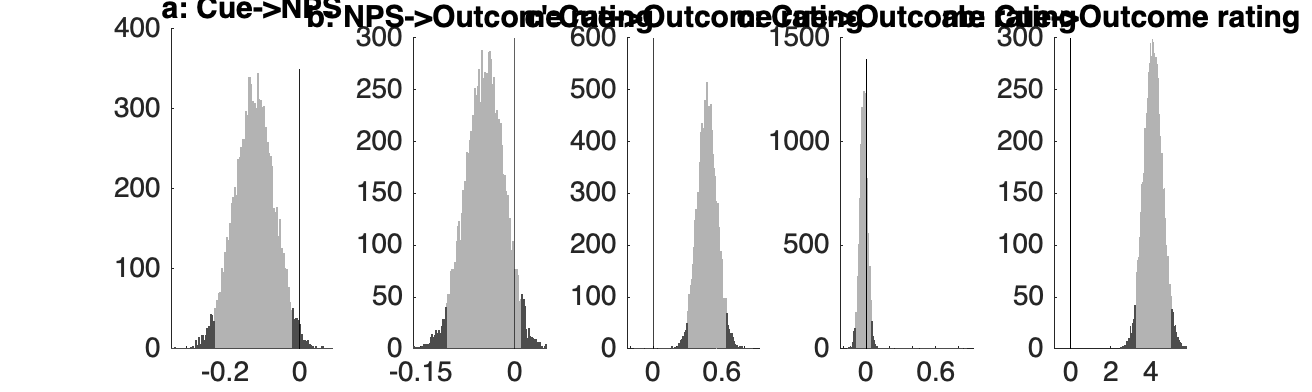

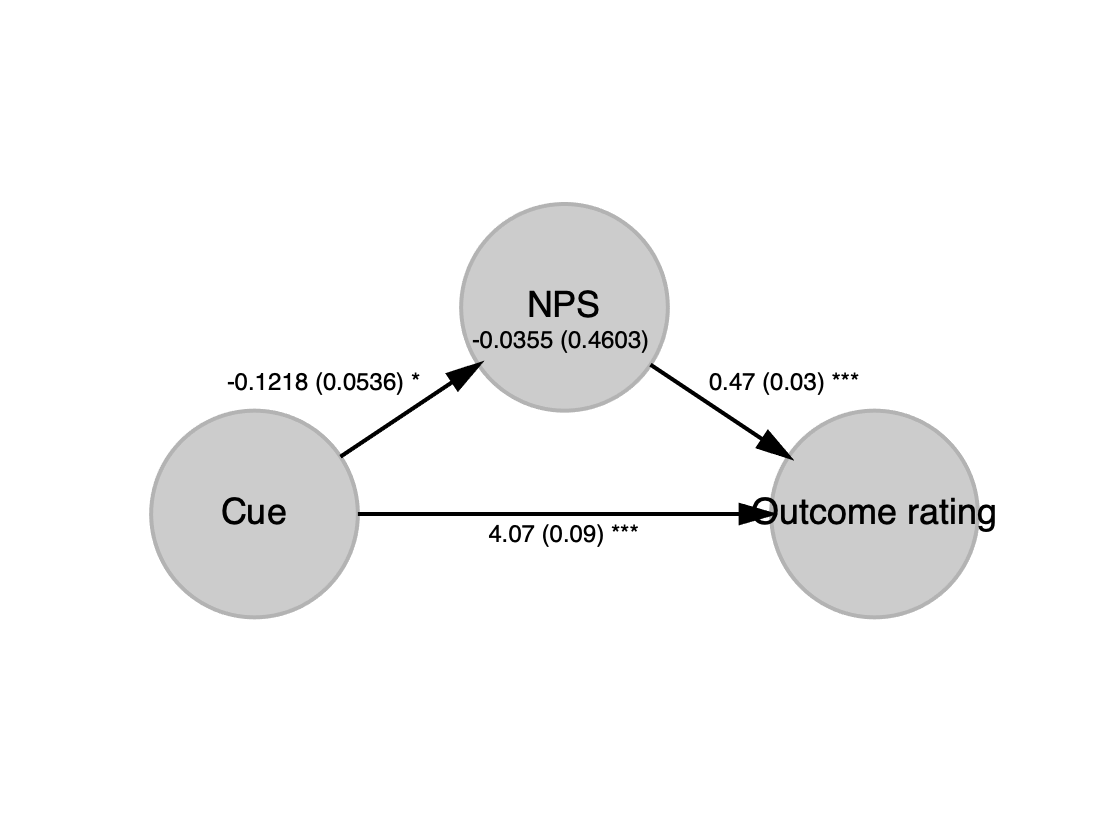

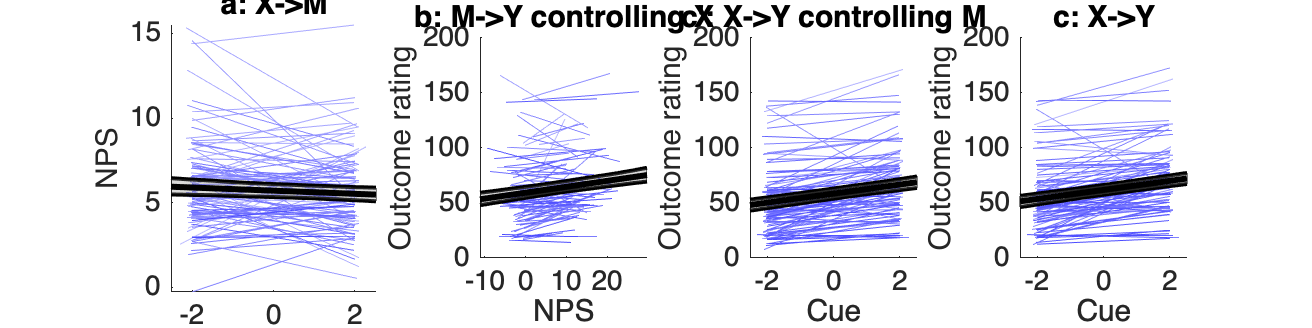

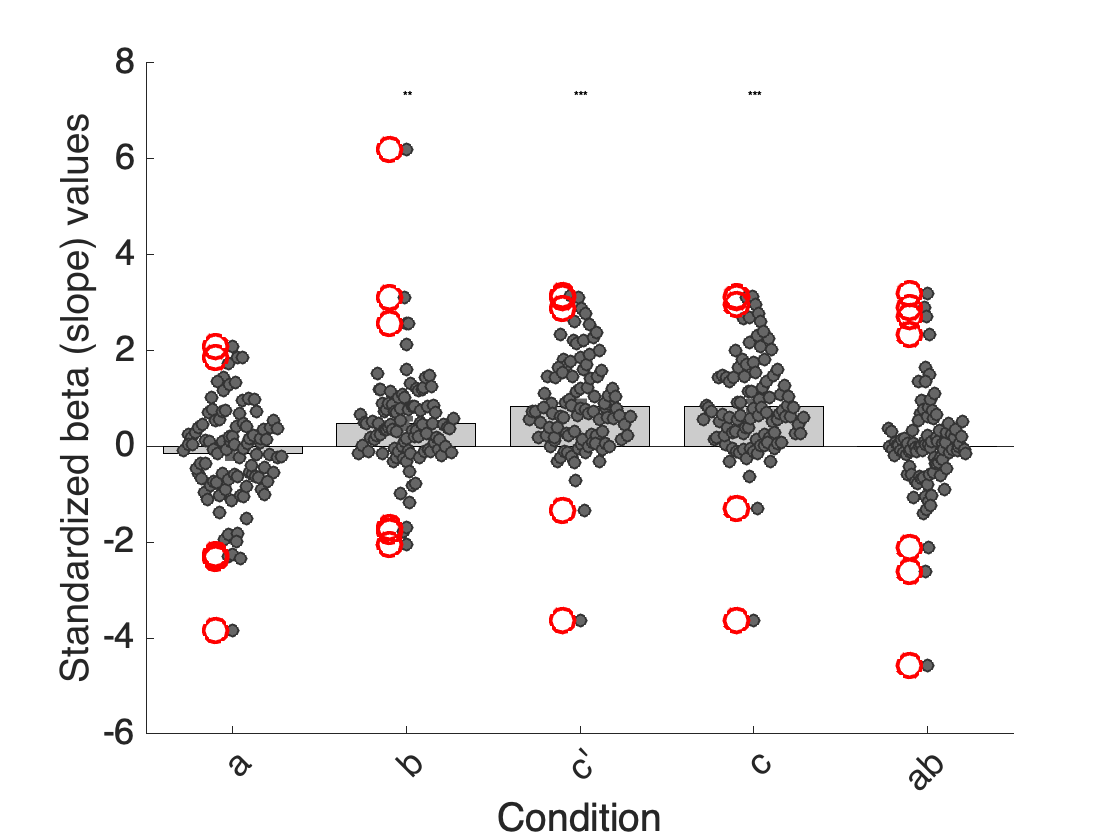

Mediation scatterplots:
Replications:  98
Covariates controlled for in all regressions:  98 predictors
Additional mediators controlled for in outcome predictions:   1 predictors


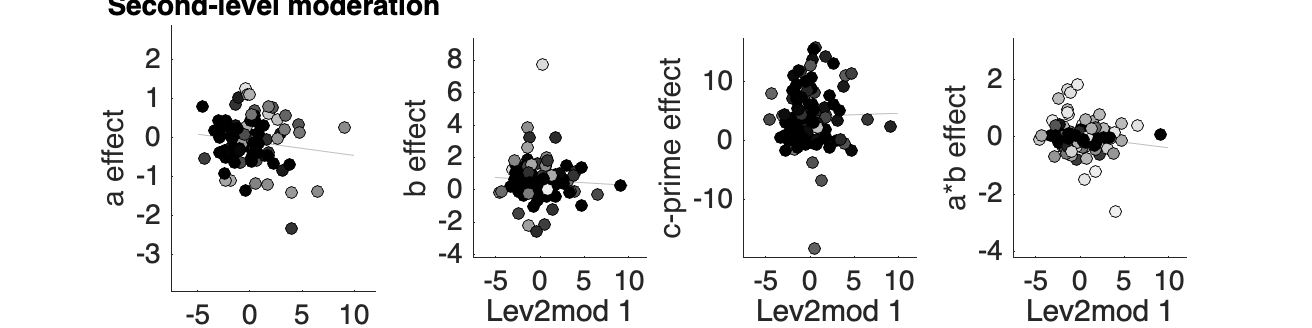


________________________________________
Average p-value tolerance (average max alpha): 0.0060

Multi-level model
	a	b	c'	c	ab	
Coeff	-0.12	0.47	4.07	4.08	-0.04	
STE	0.05	0.09	0.46	0.46	0.02	
t (~N)	-2.27	5.42	8.85	8.91	-1.57	
Z	-2.19	3.66	3.73	3.75	-1.70	
p	0.0288	0.0003	0.0002	0.0002	0.0888	

________________________________________

________________________________________
Second Level Moderator
Multi-level model
	a	b	c'	c	ab	
Coeff	-0.05	-0.02	0.12	0.09	-0.01	
STE	0.03	0.03	0.19	0.18	0.01	
t (~N)	-1.57	-0.68	0.63	0.48	-1.16	
Z	-1.44	-0.71	0.68	0.54	-1.46	
p	0.1496	0.4786	0.4981	0.5894	0.1440	

________________________________________
Total time: 120 s



moderator = scale(meanm, 1); 
[paths_M_tolerance, stats_M_tolerance] = mediation(model1_Xtrimmed, model1_Ytrimmed, model1_Mtrimmed, ...
    'covs', cov_mediation_paincue_trimmed ,  'boot', 'verbose','plots', ...
    'names', {'Cue', 'Outcome rating', 'NPS' },  'bootsamples', 10000, 'L2M', moderator);

%    
    

%% check:
% Obtain lengths of each trimmed variable
Ydata_lengths = cellfun(@length, model1_Ytrimmed);
Xdata_lengths = cellfun(@length, model1_Xtrimmed);
Mdata_lengths = cellfun(@length, model1_Mtrimmed);
cov_lengths = cellfun(@length, cov_mediation_paincue_trimmed);

% Create a matrix of the lengths
all_lengths = [Ydata_lengths; Xdata_lengths; Mdata_lengths; cov_lengths];

% Check if all lengths are equal across each set of variables
are_lengths_equal = all(diff(all_lengths) == 0);

% If not all lengths are equal, identify which ones differ
if ~are_lengths_equal
    [rows, cols] = find(diff(all_lengths) ~= 0);
    for i = 1:length(rows)
        fprintf('Discrepancy found in subject %d between variables %d and %d.\n', cols(i), rows(i), rows(i)+1);
    end
else
    disp('All lengths are equal.');
end

All lengths are equal.



%% check na
% Check for NaN values in each cell of the cell arrays
hasNaN_Y = cellfun(@(x) any(isnan(x)), model1_Ytrimmed);
hasNaN_X = cellfun(@(x) any(isnan(x)), model1_Xtrimmed);
hasNaN_M = cellfun(@(x) any(isnan(x)), model1_Mtrimmed);
hasNaN_cov = cellfun(@(x) any(isnan(x)), cov_mediation_paincue_trimmed);

% Summarize the NaN checks to see if any cell array contains NaN values
sumHasNaN_Y = any(hasNaN_Y);
sumHasNaN_X = any(hasNaN_X);
sumHasNaN_M = any(hasNaN_M);
sumHasNaN_cov = any(hasNaN_cov);

% Display results
disp(['model1_Ytrimmed contains NaN: ', num2str(sumHasNaN_Y)]);

model1_Ytrimmed contains NaN: 0


disp(['model1_Xtrimmed contains NaN: ', num2str(sumHasNaN_X)]);

model1_Xtrimmed contains NaN: 0


disp(['model1_Mtrimmed contains NaN: ', num2str(sumHasNaN_M)]);

model1_Mtrimmed contains NaN: 0


disp(['cov_mediation_paincue_trimmed contains NaN: ', num2str(sumHasNaN_cov)]);

cov_mediation_paincue_trimmed contains NaN: 0




%% plot
colors = seaborn_colors(length(model1_Xtrimmed));
barplot_columns(model1_X, 'nofig', 'noviolin', 'plotout', 'nostarts', 'notable', 'colors', colors, 'nobars')

ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
      point_han1: {72×98 cell}
        text_han: {72×98 cell}
       point_han: {72×98 cell}
    star_handles: [23.0010 24.0010 25.0010 26.0010 27.0010 28.0010 29.0010 30.0010 31.0010 32.0010 33.0010 34.0010 35.0010 36.0010 37.0010 38.0010 39.0010 40.0010 41.0010 42.0010 43.0011 44.0011 45.0011 46.0011 47.0011 48.0011 49.0011 50.0011 51.0011 … ]


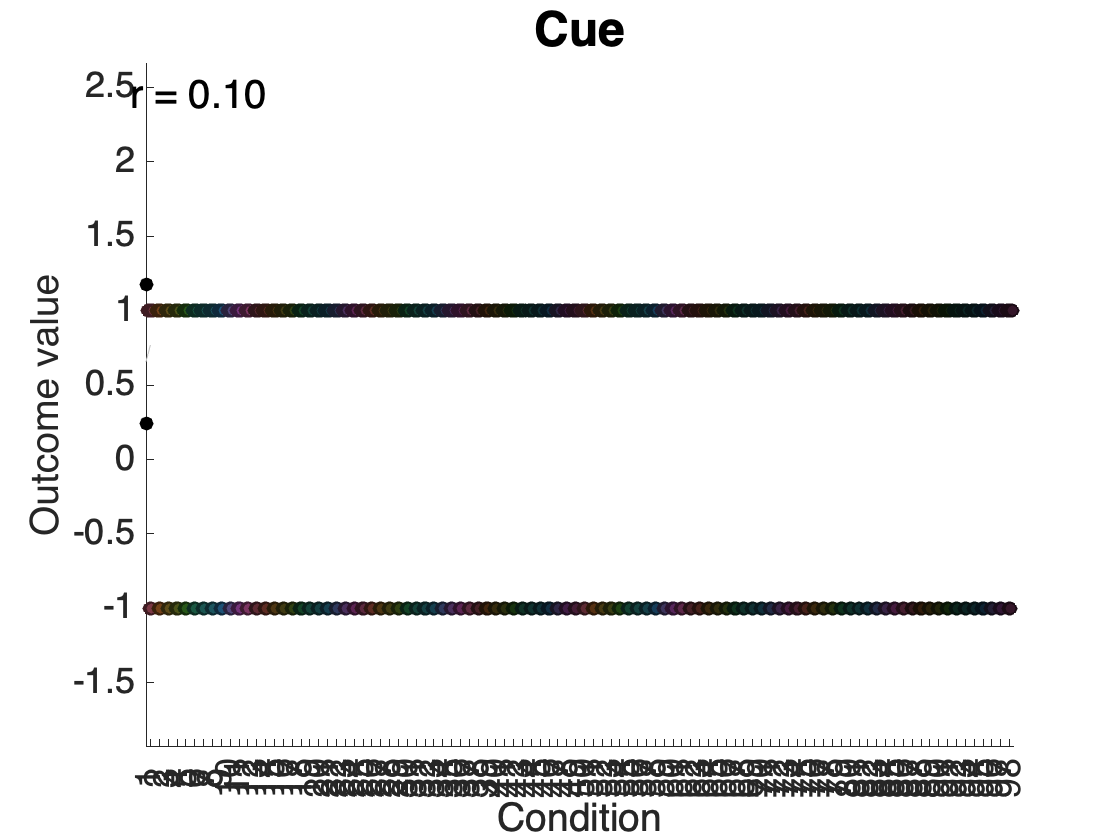

title('Cue');

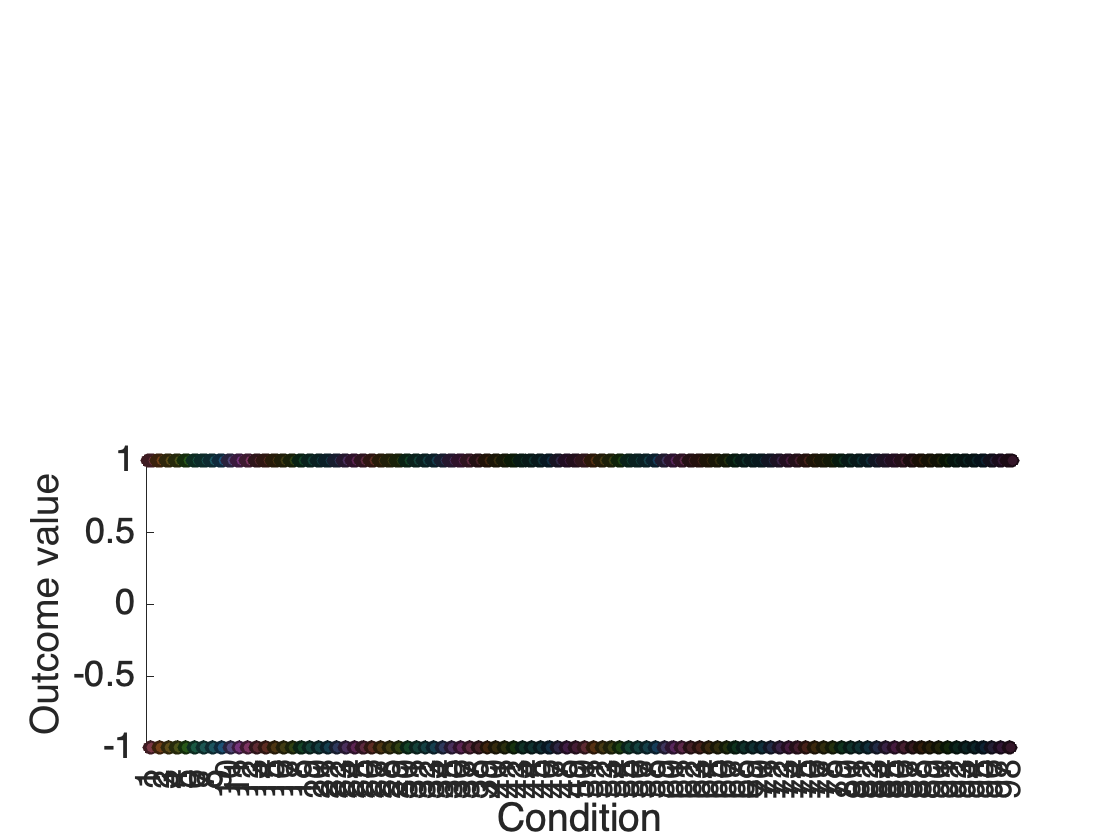

ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
      point_han1: {72×98 cell}
        text_han: {72×98 cell}
       point_han: {72×98 cell}
    star_handles: [23.0011 24.0011 25.0011 26.0011 27.0011 28.0011 29.0011 30.0011 31.0011 32.0011 33.0011 34.0011 35.0011 36.0011 37.0011 38.0011 39.0011 40.0011 41.0011 42.0011 43.0012 44.0012 45.0012 46.0012 47.0012 48.0012 49.0012 50.0012 51.0012 … ]


subplot(2,1,2);
barplot_columns(model1_Xtrimmed, 'nofig', 'noviolin', 'plotout', 'nostarts', 'notable', 'colors', colors, 'nobars')

drawnow, snapnow


%% plot

% Correlations between variables within- and between-person

meanx = cellfun(@nanmean, model1_Xtrimmed)';

Unrecognized function or variable 'model1_X_trimmed'.

meany = cellfun(@nanmean, model1_Ytrimmed)';
meanm = cellfun(@nanmean, model1_Mtrimmed)';


create_figure('Cue vs. Pain');
  set(gca, 'FontSize', 20);
  han = line_plot_multisubject(model1_X, model1_Y, 'n_bins', 5);
  title('Cue vs. Pain');
  xlabel('Cue, Quintiles');

  figure; plot_correlation_samefig(meanx, meany, [], 'ko');
  xlabel('Cue')
  ylabel('Pain, Quintiles')


create_figure('NPS vs. Pain');
  set(gca, 'FontSize', 20);
  han = line_plot_multisubject(model1_M, model1_Y, 'n_bins', 5);
  title('NPS vs. Pain');
  xlabel('Deciles of fitted response');

  figure; plot_correlation_samefig(meanm, meany, [], 'ko');
  xlabel('NPS, Quintiles')
  ylabel('Pain, Quintiles')


create_figure('Expectation vs. NPS');
  set(gca, 'FontSize', 20);
  han = line_plot_multisubject(model1_X, model1_M, 'n_bins', 5);
  title('Cue vs. NPS');
  xlabel('Deciles of fitted response');

  figure; plot_correlation_samefig(meanx, meanm, [], 'ko');
  xlabel('Cue, Quintiles')
  ylabel('NPS, Quintiles')

    


% partial correlations between expectancy, pain and NPS
partialr = partialcorr([meanx meany meanm]);

t = array2table(partialr, 'VariableNames', {'Cue' 'Pain' 'NPS'});
t

histogram(moderator);
xlabel('NPS sensitivity');
ylabel('Frequency');
title('Plot moderator distribution');